# Target classification based on MATLAB -- taking animal classification as an example

Author:Peiyu Chen SJTU

Email：pietychen@sjtu.edu.cn

CNN (convolutional neural network) is a kind of feedforward neural network with depth structure and convolution computation.

## Convolution

Take an explanation from Zhihu as an example: "the superposition of what you made your girlfriend angry at different times in the past contributes to her bad mood now is convolution."

In image problems, convolution can be understood as a calculation to extract image features:

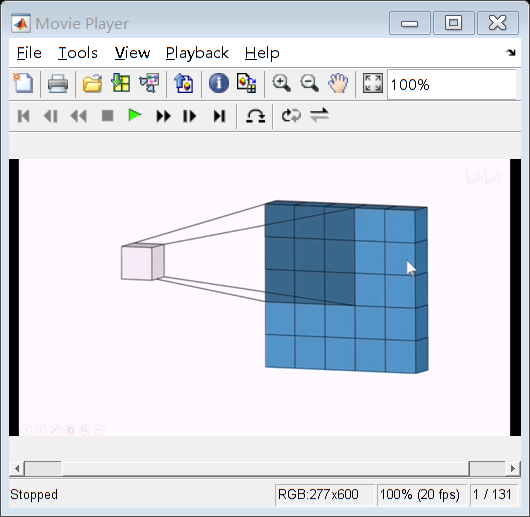

[A,map]=imread('./convolution.gif','frames','all');
mov=immovie(A,map);
implay(mov)

## Convolution neural network

Neural network is a kind of artificial intelligence like machine learning technology, which simulates human brain. The basic unit of neural network is neuron. The neuron model is a model including input, output and calculation functions. The input can be compared to the dendrite of a neuron, the output can be compared to the axon of a neuron, and the calculation can be compared to the nucleus. Connections are the most important thing in neurons. Each connection has a weight. An artificial neural network training algorithm is to adjust the weight value to the best, so as to make the prediction effect of the whole network the best.

However, if we use enough convolution layers, we can get enough advanced and rich image features.

Convolution neural network is the combination of convolution layer and other neural network layers, which is used to obtain rich image features and help us complete image classification.

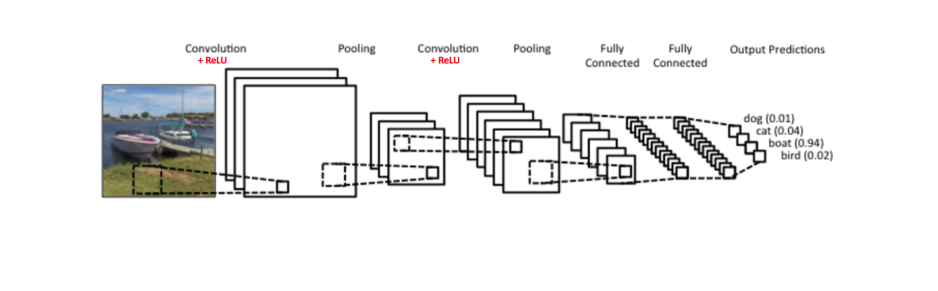

imshow(imread('./CNN.png'))

## How to design a deep neural network?

- Build your own according to your experience and needs

- "Standing on the shoulders of giants" -- pre training model and transfer learning

We use alexnet without weight as the pre training model, and modify some of its parameters to ensure the efficiency of display, so its accuracy will be reduced.

Deep network designer is an application in the deep learning toolbox, which can help us to define neural networks explicitly and generate relevant codes.

deepNetworkDesigner

clc
clear
close all

## Data preprocessing

Our data sources are Imagenet and kaggle. The original data has been converted to. JPG format through bat batch file

The purpose of data preprocessing is to normalize all images to the size of neural network input layer

file_path = './Dataset/';
format = '*.jpg';
classes = ["cat";"chicken";"cow";"dog";"sheep"];

idx = cell(size(classes,1),1);
total_sample_num = 0;

for i = 1:size(classes,1)
    class_dir = strcat(strcat(file_path,classes{i}),'/');
    %dir(strcat(class_dir,format));

image_num = 1957

image_num = 1976

image_num = 1866

image_num = 2036

image_num = 1820

    image_num = length(dir(strcat(class_dir,format)))
    idx{i} = image_num;
    total_sample_num = total_sample_num+image_num;
end

**Data set equilibrium analysis**

One of the most important requirements of classification neural network is data set balance

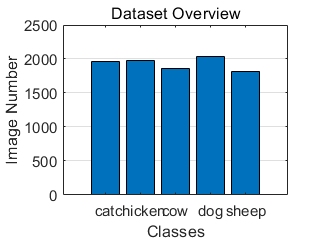

bar(cell2mat(idx))
xlabel('Classes')

xlim([-0.20 6.20])
ylim([0 2500])

set(gca,'XGrid','off','YGrid','on')
set(gca,'xticklabel',classes);


ylabel('Image Number')

total_sample_num = 9655

title('Dataset Overview')
clf
total_sample_num

## Image preprocessing example

sz_img = 128;
images = zeros(sz_img,sz_img,3);
labels = cell(total_sample_num,1);

**Unprocessed images**

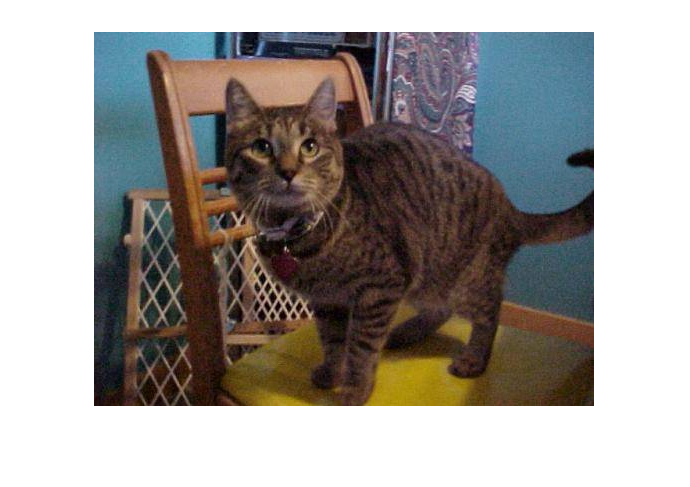

img = imread('./Dataset/cat/cats_00001.jpg');
imshow(img)

**Image after processing**

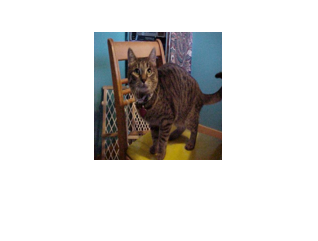

img = imresize(img,[sz_img,sz_img]);
images = img;
imshow(img)

clf

## Data reading, preprocessing and storage

***It takes a long time to read and preprocess data, so it is recommended to use it directly dataset.mat***

After the data is read successfully, it will be saved in a mat file, and it will greatly improve the efficiency of the program when it is used

k = 0;
for i = 1:size(classes,1)
    class_dir = strcat(strcat(file_path,classes{i}),'/');
    begin_idx = k+1
    end_idx = k+idx{i}
    for j = begin_idx:end_idx
        temp = dir(strcat(class_dir,format));
        image_name = temp(j-k).name;
        img = imresize(imread(strcat(class_dir,image_name)),[sz_img,sz_img]);
        images(:,:,:,j) = img;
        labels{j} = i-1;
    end
    k = k+idx{i};
end

begin_idx = 1

end_idx = 1957

begin_idx = 1958

end_idx = 3933

begin_idx = 3934

end_idx = 5799

begin_idx = 5800

end_idx = 7835

begin_idx = 7836

end_idx = 9655

save dataset.mat images labels

## Read data

load dataset.mat
whos

  Name                     Size                        Bytes  Class     Attributes

  A                      277x600x1x131              21772200  uint8               
  begin_idx                1x1                             8  double              
  class_dir                1x16                           32  char                
  classes                  5x1                           366  string              
  end_idx                  1x1                             8  double              
  file_path                1x10                           20  char                
  format                   1x5                            10  char                
  i                        1x1                             8  double              
  idx                      5x1                           560  cell                
  image_name               1x70                          140  char                
  image_num                1x1                             8  double              
  i

## Display some images and labels

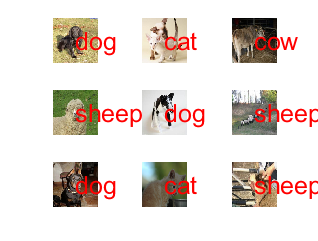

for i = 1:9
    idx = round(unifrnd(1,total_sample_num));
    subplot(3,3,i);
    imshow(images(:,:,:,idx))
    text(sz_img/2,sz_img/2,classes{double(labels{idx})+1},'color','r','fontsize',15)
end

clf

## Split data set

The whole data set is randomly scrambled and divided into training set, verification set and test set.

Scrambling the data set can improve the training accuracy.

We use the training set to train the weight parameters of the neural network, use the verification set to verify the training results, and finally calculate the accuracy on the test set.

Y = categorical(labels); 

rand_idx = randperm(size(images,4));  
num_train = round(0.6*size(images,4)); 
num_val = round(0.3*size(images,4));  

X_train = double(images(:,:,:,rand_idx(1:num_train)))./255;
X_val = double(images(:,:,:,rand_idx(num_train+1:num_train+num_val)))./255;
X_test = double(images(:,:,:,rand_idx(num_train+num_val+1:end)))./255;  
    
Y_train = Y(rand_idx(1:num_train),:);
Y_val = Y(rand_idx(num_train+1:num_train+num_val),:);
Y_test = Y(rand_idx(num_train+num_val+1:end),:);

## Define neural network structure

Input layer: input a picture of specified size

Convolution layer: extracting image features

Activation layer: convert linear function to nonlinear, so that any function can be approximated

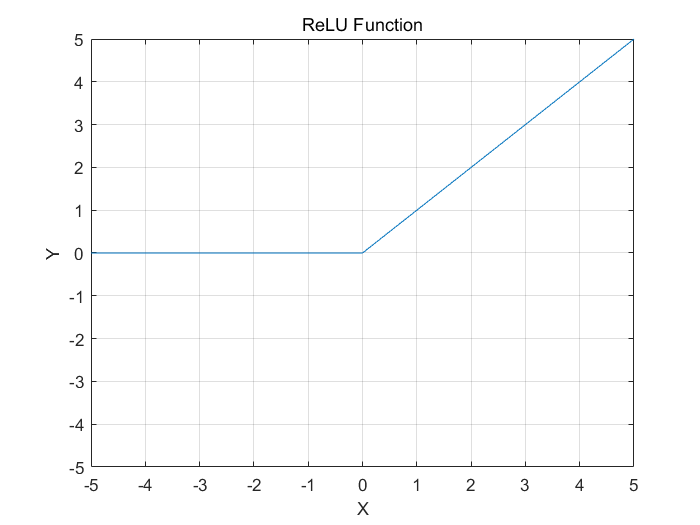

figure('NumberTitle', 'off', 'Name', 'ReLU function');

x=-5:0.1:5;
y=max(0,x);

plot(x,y);

xlabel('X');ylabel('Y');
grid on;
axis on;
axis([-5,5,-5,5]);

title('ReLU Function');

clf

Pooling layer: discarding some features to prevent over fitting

Full connection layer: the high-dimensional vector generated by neural network is expanded to output the result

## Define neural network structure

layers = [
    imageInputLayer([128 128 3],"Name","imageinput")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(1000,"Name","fc8","BiasLearnRateFactor",2)
    fullyConnectedLayer(5,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Visual neural network

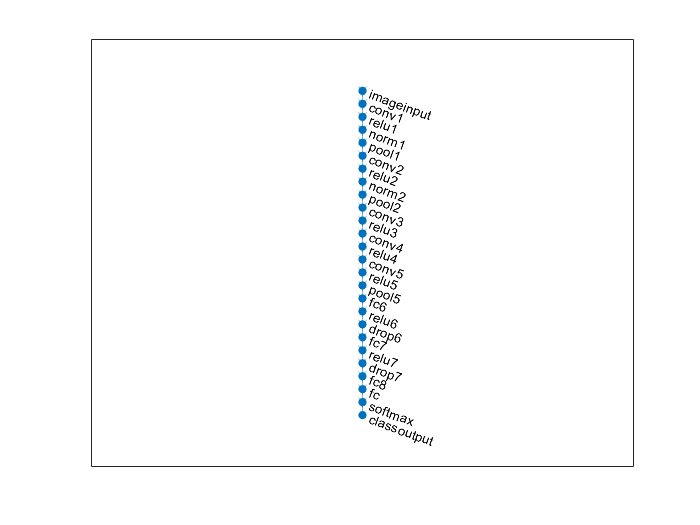

plot(layerGraph(layers));

analyzeNetwork(layers)
clf

## Specify the training parameters and train the network

The specification of super parameters: that is, the process of "alchemy" as we usually call it, requires experience and trial to obtain a neural network with high accuracy.

在单 GPU 上训练。
正在初始化输入数据归一化。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　１　｜　　　　１　｜　　　　　００：００：０４　｜　　　１８．７５％　｜　　１９．５４％　｜　　１．６１２０　｜　１．６０９５　｜　　０．００７０　｜


｜　　　１　｜　　　５０　｜　　　　　００：００：０７　｜　　　１５．６３％　｜　　　　　　　　　｜　　１．６８０６　｜　　　　　　　　｜　　０．００７０　｜


｜　　　１　｜　　１００　｜　　　　　００：００：１０　｜　　　２５．００％　｜　　２７．６５％　｜　　１．５８２７　｜　１．６０１５　｜　　０．００７０　｜


｜　　　１　｜　　１５０　｜　　　　　００：００：１３　｜　　　２８．１３％　｜　　　　　　　　　｜　　１．５１６３　｜　　　　　　　　｜　　０．００７０　｜


｜　　　２　｜　　２００　｜　　　　　００：００：１６　｜　　　５０．００％　｜　　３３．３１％　｜　　１．４３２５　｜　１．４９５８　｜　　０．００７０　｜


｜　　　２　｜　　２５０　｜　　　　　００：００：１９　｜　　　４０．６３％　｜　　　　　　　　　｜　　１．４８３２　｜　　　　　　　　｜　　０．００７０　｜


｜　　　２　｜　　３００　｜　　　　　００：００：２２　｜　　　４０．６３％　｜　　３８．５２％　｜　　１．３５６２　｜　１．３８７８　｜　　０．００７０　｜


｜　　　２　｜　　３５０　｜　　　　　００：００：２４　｜　　　４３．７５％　｜　　　　　　　　　｜　　１．３８５２　｜　　　　　　　　｜　　０．００７０　｜


｜　　　３　｜　　４００　｜　　　　　００：００：２８　｜　　　１８．７５％　｜　　３９．７０％　｜　　１．８３６０　｜　１．３５４２　｜　　０．００７０　｜


｜　　　３　｜　　４５０　｜　　　　　００：００：３０　｜　　　３４．３８％　｜　　　　　　　　　｜　　１．５５３２　｜　　　　　　　　｜　　０．００７０　｜


｜　　　３　｜　　５００　｜　　　　　００：００：３４　｜　　　５０．００％　｜　　４３．８７％　｜　　１．２４９８　｜　１．３４２８　｜　　０．００７０　｜


｜　　　４　｜　　５５０　｜　　　　　００：００：３６　｜　　　２８．１３％　｜　　　　　　　　　｜　　１．３９７８　｜　　　　　　　　｜　　０．００７０　｜


｜　　　４　｜　　６００　｜　　　　　００：００：４０　｜　　　６８．７５％　｜　　５０．８５％　｜　　１．００５４　｜　１．１８０３　｜　　０．００７０　｜


｜　　　４　｜　　６５０　｜　　　　　００：００：４２　｜　　　３７．５０％　｜　　　　　　　　　｜　　１．３４４２　｜　　　　　　　　｜　　０．００７０　｜


｜　　　４　｜　　７００　｜　　　　　００：００：４５　｜　　　４３．７５％　｜　　４８．７１％　｜　　１．１９５０　｜　１．２５８６　｜　　０．００７０　｜


｜　　　５　｜　　７５０　｜　　　　　００：００：４８　｜　　　４３．７５％　｜　　　　　　　　　｜　　１．１７６８　｜　　　　　　　　｜　　０．００７０　｜


｜　　　５　｜　　８００　｜　　　　　００：００：５１　｜　　　５９．３８％　｜　　５４．４０％　｜　　０．８６２０　｜　１．１１２２　｜　　０．００７０　｜


｜　　　５　｜　　８５０　｜　　　　　００：００：５３　｜　　　５０．００％　｜　　　　　　　　　｜　　０．８７８７　｜　　　　　　　　｜　　０．００７０　｜


｜　　　５　｜　　９００　｜　　　　　００：００：５７　｜　　　５３．１３％　｜　　５６．９２％　｜　　１．０７３４　｜　１．０６８５　｜　　０．００７０　｜


｜　　　６　｜　　９５０　｜　　　　　００：００：５９　｜　　　５０．００％　｜　　　　　　　　　｜　　１．０７２７　｜　　　　　　　　｜　　０．００７０　｜


｜　　　６　｜　１０００　｜　　　　　００：０１：０３　｜　　　６５．６３％　｜　　５７．４７％　｜　　１．００９９　｜　１．０４１９　｜　　０．００７０　｜


｜　　　６　｜　１０５０　｜　　　　　００：０１：０５　｜　　　４６．８８％　｜　　　　　　　　　｜　　１．２６４６　｜　　　　　　　　｜　　０．００７０　｜


｜　　　７　｜　１１００　｜　　　　　００：０１：０９　｜　　　６２．５０％　｜　　５８．５１％　｜　　０．７８２２　｜　１．０２４９　｜　　０．００７０　｜


｜　　　７　｜　１１５０　｜　　　　　００：０１：１１　｜　　　６８．７５％　｜　　　　　　　　　｜　　０．８７０４　｜　　　　　　　　｜　　０．００７０　｜


｜　　　７　｜　１２００　｜　　　　　００：０１：１４　｜　　　５９．３８％　｜　　５９．５８％　｜　　１．０３７７　｜　０．９７８２　｜　　０．００７０　｜


｜　　　７　｜　１２５０　｜　　　　　００：０１：１７　｜　　　７５．００％　｜　　　　　　　　　｜　　０．７７６５　｜　　　　　　　　｜　　０．００７０　｜


｜　　　８　｜　１３００　｜　　　　　００：０１：２０　｜　　　６２．５０％　｜　　６１．３４％　｜　　０．８８０３　｜　０．９８５６　｜　　０．００７０　｜


｜　　　８　｜　１３５０　｜　　　　　００：０１：２２　｜　　　６８．７５％　｜　　　　　　　　　｜　　０．８７２９　｜　　　　　　　　｜　　０．００７０　｜


｜　　　８　｜　１４００　｜　　　　　００：０１：２６　｜　　　４６．８８％　｜　　５９．４１％　｜　　１．２１４８　｜　０．９９２４　｜　　０．００７０　｜


｜　　　９　｜　１４５０　｜　　　　　００：０１：２８　｜　　　６２．５０％　｜　　　　　　　　　｜　　０．８２８６　｜　　　　　　　　｜　　０．００７０　｜


｜　　　９　｜　１５００　｜　　　　　００：０１：３２　｜　　　８１．２５％　｜　　６１．５１％　｜　　０．５８９３　｜　０．９７７１　｜　　０．００７０　｜


｜　　　９　｜　１５５０　｜　　　　　００：０１：３４　｜　　　７５．００％　｜　　　　　　　　　｜　　０．７０２４　｜　　　　　　　　｜　　０．００７０　｜


｜　　　９　｜　１６００　｜　　　　　００：０１：３７　｜　　　７５．００％　｜　　６５．２７％　｜　　０．４４１０　｜　０．９２６７　｜　　０．００７０　｜


｜　　１０　｜　１６５０　｜　　　　　００：０１：４０　｜　　　７５．００％　｜　　　　　　　　　｜　　０．６７４８　｜　　　　　　　　｜　　０．００７０　｜


｜　　１０　｜　１７００　｜　　　　　００：０１：４３　｜　　　９０．６３％　｜　　６５．６９％　｜　　０．４９１２　｜　０．９１８８　｜　　０．００７０　｜


｜　　１０　｜　１７５０　｜　　　　　００：０１：４５　｜　　　４０．６３％　｜　　　　　　　　　｜　　１．３４８４　｜　　　　　　　　｜　　０．００７０　｜


｜　　１０　｜　１８００　｜　　　　　００：０１：４９　｜　　　８１．２５％　｜　　６３．８２％　｜　　０．４３５６　｜　０．９９８８　｜　　０．００７０　｜


｜　　１１　｜　１８５０　｜　　　　　００：０１：５１　｜　　　６８．７５％　｜　　　　　　　　　｜　　０．６１７５　｜　　　　　　　　｜　　０．００７０　｜


｜　　１１　｜　１９００　｜　　　　　００：０１：５５　｜　　　７８．１３％　｜　　６６．２１％　｜　　０．６４１０　｜　０．９２６２　｜　　０．００７０　｜


｜　　１１　｜　１９５０　｜　　　　　００：０１：５７　｜　　　８１．２５％　｜　　　　　　　　　｜　　０．４３９５　｜　　　　　　　　｜　　０．００７０　｜


｜　　１２　｜　２０００　｜　　　　　００：０２：０１　｜　　　７１．８８％　｜　　６６．９７％　｜　　０．６７２９　｜　０．９０６１　｜　　０．００７０　｜


｜　　１２　｜　２０５０　｜　　　　　００：０２：０３　｜　　　７８．１３％　｜　　　　　　　　　｜　　０．７０７９　｜　　　　　　　　｜　　０．００７０　｜


｜　　１２　｜　２１００　｜　　　　　００：０２：０６　｜　　　６８．７５％　｜　　６７．３１％　｜　　０．８１６９　｜　０．９３７４　｜　　０．００７０　｜


｜　　１２　｜　２１５０　｜　　　　　００：０２：０９　｜　　　７１．８８％　｜　　　　　　　　　｜　　０．６４９８　｜　　　　　　　　｜　　０．００７０　｜


｜　　１２　｜　２１７２　｜　　　　　００：０２：１１　｜　　　７５．００％　｜　　６３．１０％　｜　　０．５６７４　｜　１．０２２２　｜　　０．００７０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


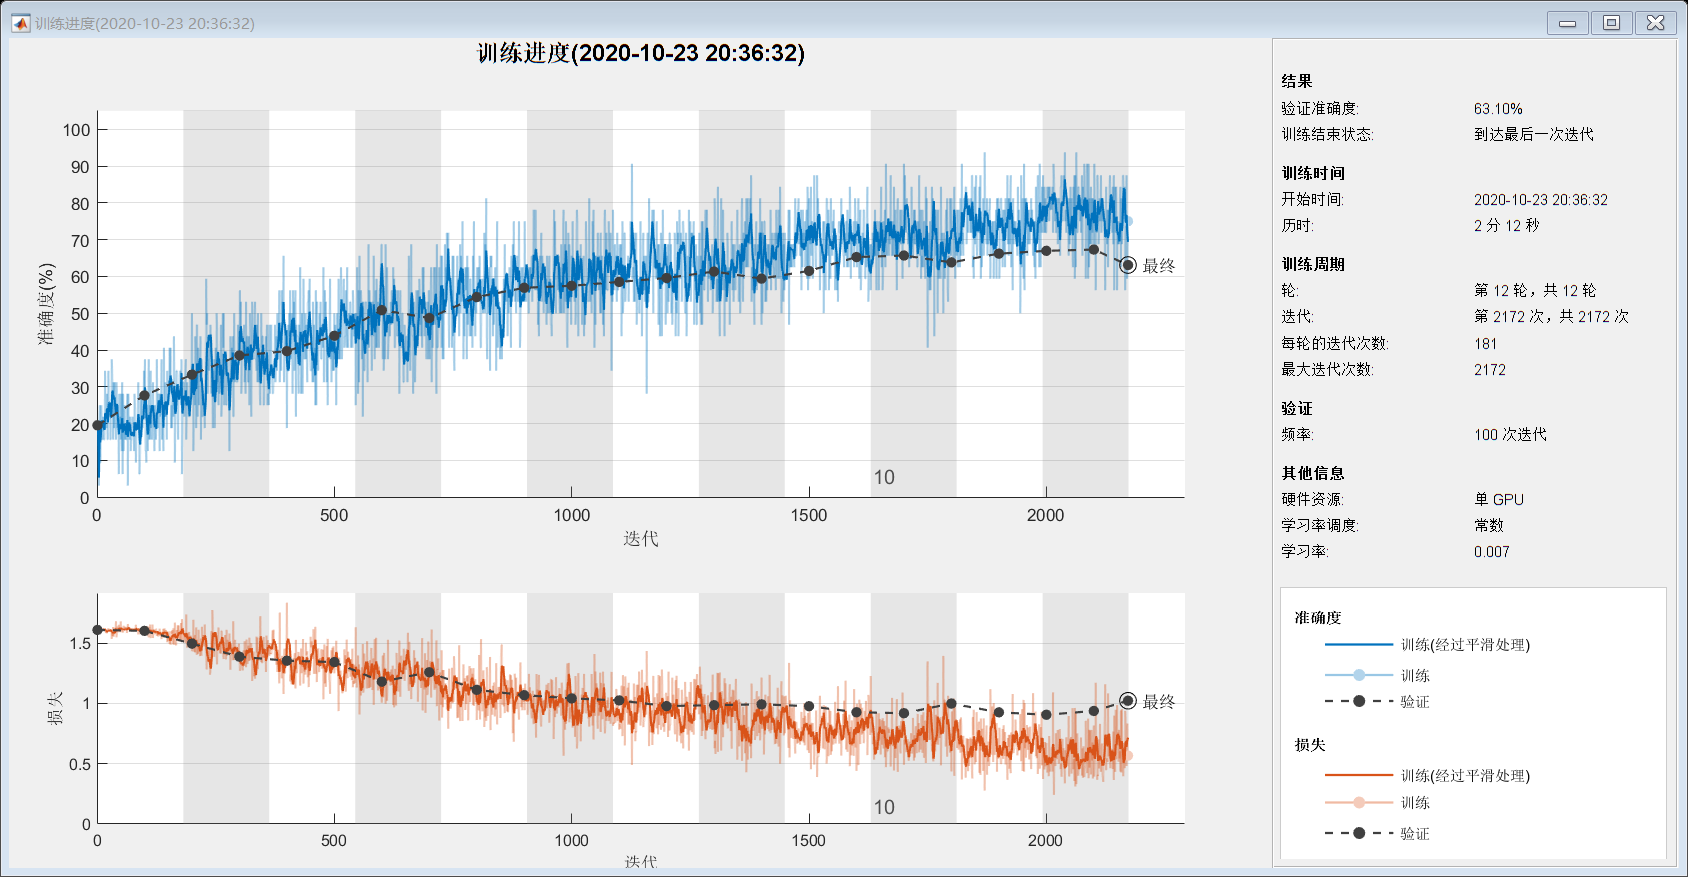

options = trainingOptions('sgdm',...                              
                          'MiniBatchSize',32, ...
                          'MaxEpochs',12,...                 
                          'ValidationData',{X_val,Y_val},... 
                          'Verbose',true, ...                
                          'Shuffle','every-epoch', ...
                          'ValidationFrequency',100, ...
                          'InitialLearnRate',0.007,...
                          'Plots','training-progress');
net_cnn = trainNetwork(X_train,Y_train,layers,options);

## Characteristics of convolution layer

Taking the first level convolution as an example, it extracts the bottom features of the image, such as the contour of the image

With the development of convolution neural network, low-level features (such as image contour) will gradually lose, while high-level features (such as image texture) will gradually highlight

layer = 2;
name = net_cnn.Layers(layer).Name

name = 'conv1'

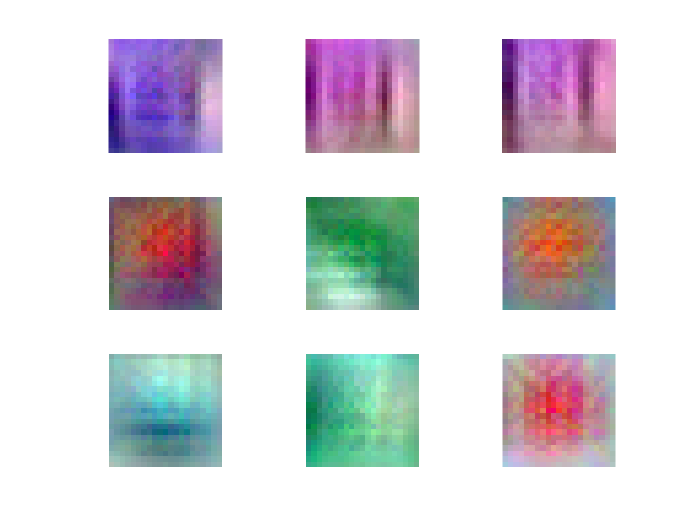

channels = 1:16;
I = deepDreamImage(net_cnn,layer,channels, ...
    'PyramidLevels',3, ...
    'Verbose',0);
figure
for i = 1:9
    subplot(3,3,i)
    imshow(I(:,:,:,i))
end

clf

## Verification set accuracy

The accuracy of the verification set obtained by changing the parameters several times is as follows:

val_acc = [
    61.58 65.25 68.00 66.39 65.82 65.72 64.98 64.37 64.19 64.01 63.96;
    61.79 65.38 68.12 66.47 66.00 65.79 65.32 64.97 64.44 64.17 64.01;
    62.01 65.49 68.33 66.56 66.14 65.90 65.56 65.12 64.88 64.39 64.17;
    62.03 65.51 68.36 66.61 66.17 65.91 65.59 65.00 64.91 64.44 64.1;
    ]; 

## Validation set accuracy image

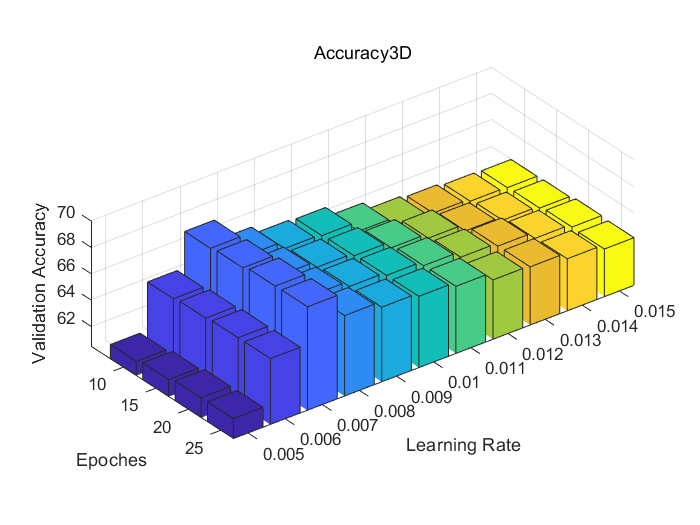

bar3(val_acc);

set(gca,'xticklabel',0.005:0.001:0.015);
set(gca,'yticklabel',10:5:25);

zlim([60.5,70]);
xlabel('Learning Rate');
ylabel('Epoches');
zlabel('Validation Accuracy');

title('Accuracy3D');

colorbar off
clf

After verification, when the learning rate is 0.007 and the number of iterations is 20 times, the better training results can be obtained under the current network

## Test set accuracy

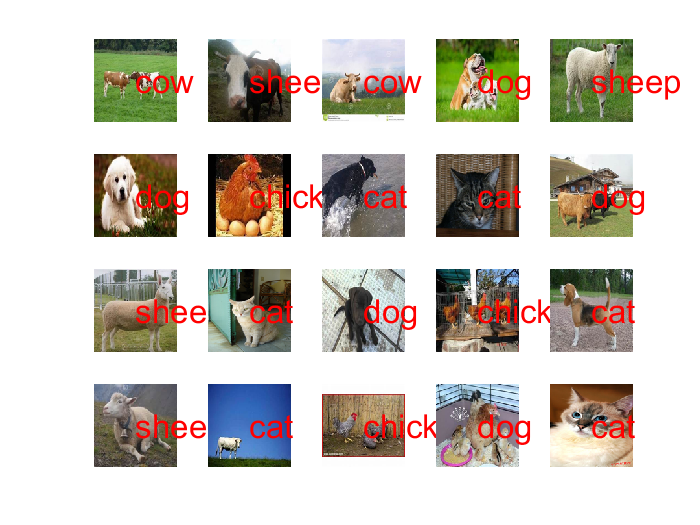

testLabel = classify(net_cnn,X_test);
for i = 1:20
    subplot(4,5,i);
    imshow(X_test(:,:,:,i))
    double(testLabel(i));
    text(sz_img/2,sz_img/2,classes{double(testLabel(i))},'color','r','fontsize',20)
end

clf
precision = sum(testLabel==Y_test)/numel(testLabel);
disp(['Test Accuracy：',num2str(precision*100),'%'])

Test Accuracy：65.8031%


## Summary

- Matlab real-time editor and deep learning toolbox complement each other. The combination of the two can clearly define and train neural networks, which is easier to use than the mainstream deep learning frameworks such as Python / tensorflow;

- The main reason for the poor training accuracy is that the convolution layer of the pre training model is not very suitable for the input size of the image of this dataset. In order to obtain high accuracy, we still need enough network building experience and training attempts.